%% 저항계산
% 예시 1 SlotLayerNumber=1 짜리 FIW
calcJMAGResistanceExamplePerCase
% 예시 2 SlotLayerNumber=2 짜리 FSCW


와이어(Wire) : strand 다발을 모아놓은 개념 

도체(Conductor)

도체수(Conductor Number)

**[Number of Turns]**

**3상 감기 설정 또는 다상 감기 설정의 경우 톱니당 코일 와이어 수를 입력합니다. 예를 들어, 하나의 위상을 2개의 톱니로 구성하고 위상당 50회전을 감는 경우 [회전 수]로 "25"를 입력합니다.**

**[Number of Coil]**

Number of coils per single phase (full model values)

Layer(Layer Number)

회로 관점

코일(Coil) - Wound(Winding) 개념 

턴수(Turn)

유효턴수(Effective Turn)

병렬회로수

Series Turn 

상당직렬턴수


$$$R_{\text {phase }}=\frac{1}{\sigma} \times \frac{L_{\text {phase }} \times K l \times N_{\text {turn }}}{S_{\text {wire }}} \times \frac{N_{\text {serial }}}{N_{\text {parallel }}}$$$


or

$$R=\frac{l}{\sigma A}=\frac{\text { 직렬 Wire 다발의 총길이 }}{\text { 도전울 } \times \text { 한 Wire다발의 단면적 }}$$ -> 병렬계산


$$
\begin{array}{l|l}
\hline \sigma & \text { Material electrical conductivity (1/(ohmm)) } \\
\hline L_{\text {phase }} & \text { Length per single coll (m). See below for the formula. } \\
\hline K l & \text { Correction factor for coil length } \\
\hline N_{\text {turn }} & \text { Number of turns (turn) } \\
\hline S_{\text {wire }} & \text { Wire cross-section area ( } \mathrm{m}^{\wedge} \text { 2) (Cross-section area per single wire } \times \text { [Number of Strands]) } \\
\hline N_{\text {serial }} & \text { The value of [Series Number] in the [Winding] tab of the [Winding Setting] dialog } \\
\hline N_{\text {parallel }} & \text { The value of [Parallel Number] in the [Winding] tab of the [Winding Setting] dialog } \\
\hline
\end{array}
$$


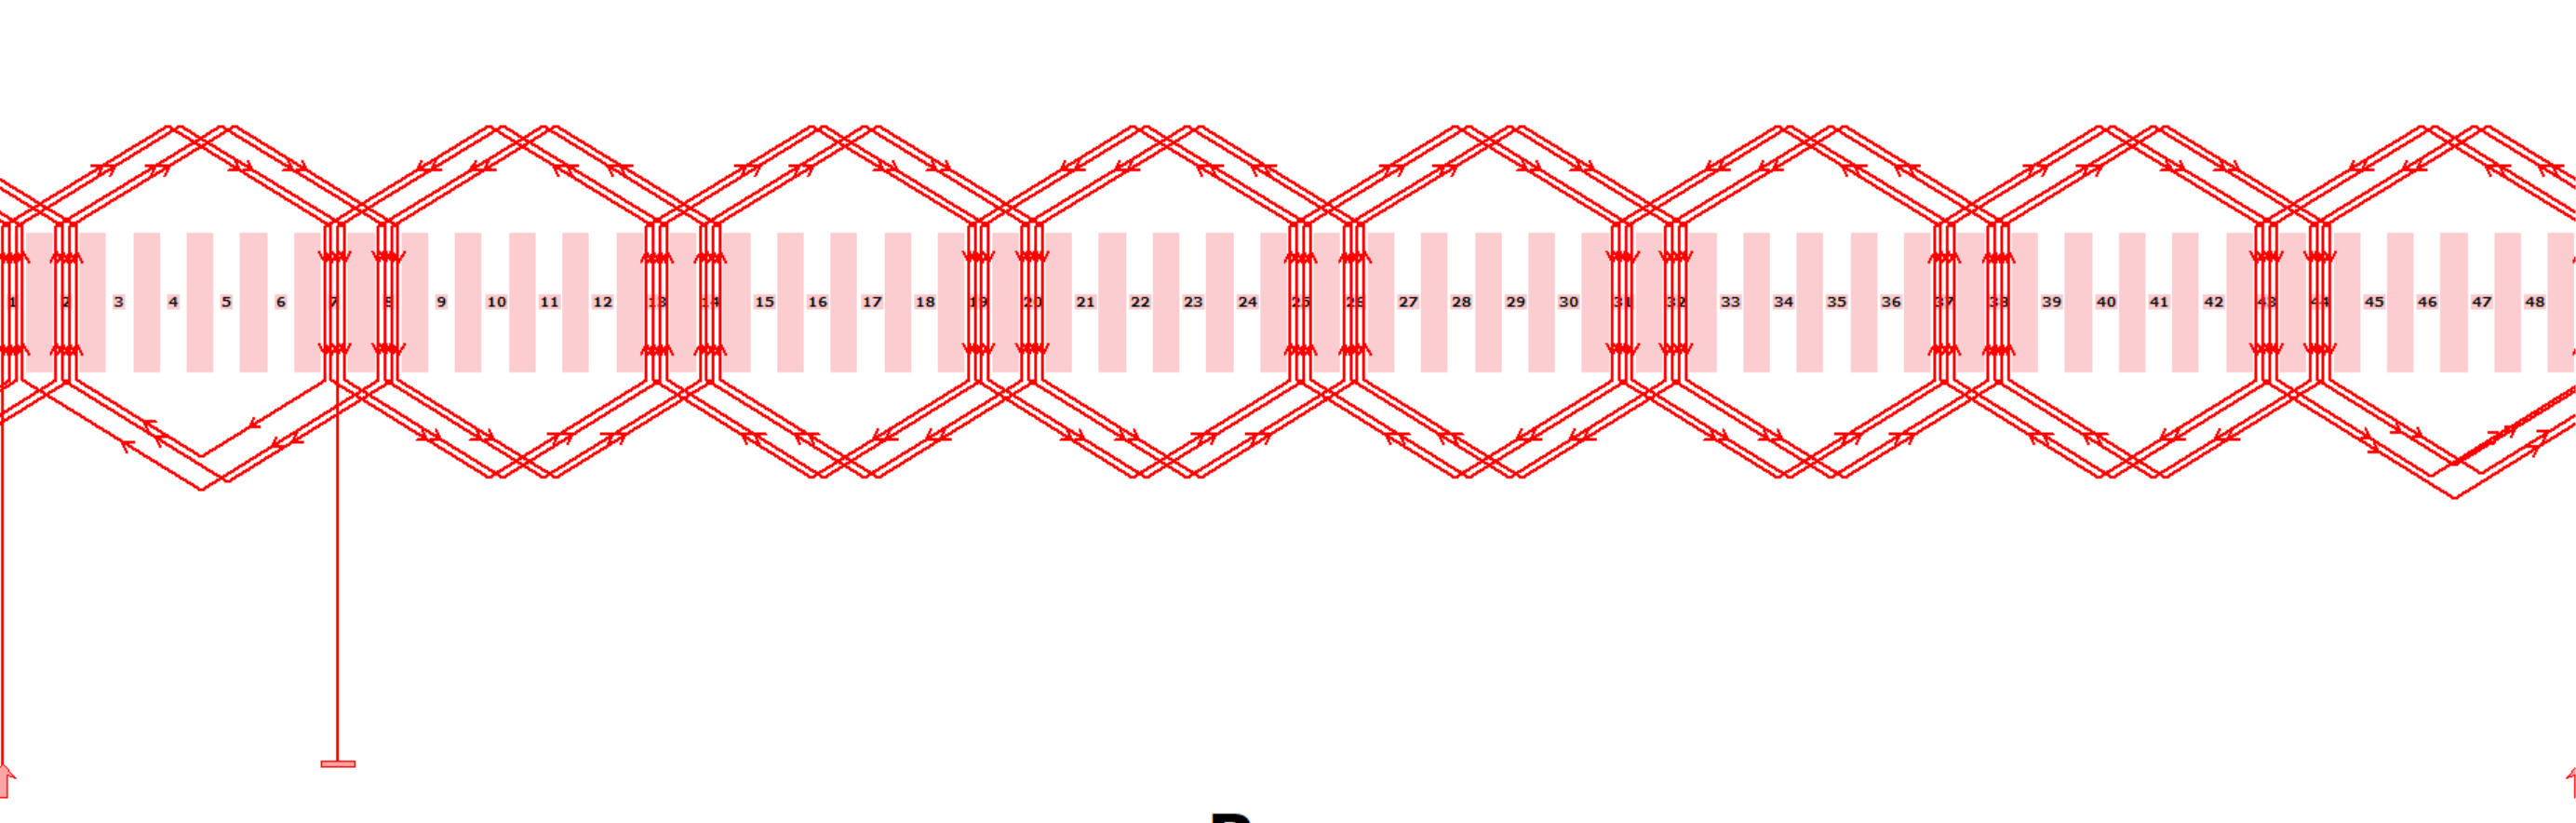

JMAG

$$L_{\text {phase }}=L_{\text {slot }}+L_{\text {end }}$$ 전체코일길이 =Active Part 코일길이+ End 코일길이

$L_{\text {slot }}=\sum(t \times 2)
$    Active Part 코일 = 적층길이 x2 (왕복이니까) 


$$$L_{e n d}=\sum_{n=1}^{N_{c o i t s}}\left(l_h+l_v\right)$$$



$$$l_h=\frac{2 \pi r}{N} \times$ pitch $\times 2$$$



$$$l_v=$ SlotLwind $\times N_{\text {coils }} \times 2$$$



$$SlotLwind=\frac{A_{\text {slot }}}{2 \times\left(r_{\max }-r_{\min }\right)}$$$


## 0 Get Slot Part From JmagDesignerPartStruct 

PartStruct=getJMAGDesignerPartStruct(app)
PartStruct=getEdgeVertexIdwithXYZCheck(PartStruct,app);
Name2="Conductor";
isInsulation=contains({PartStruct.Name},Name2);
InsulationStruct=PartStruct(isInsulation);

## 1 Check and Calc Length

### Active part Length

#### MotorCAD


MotorCADGeo=tempDefMCADMachineData4Scaling(mcad)
CoilWindingInfo=defCoilWindingInfoStruct(MotorCADGeo) 
MotorCADGeo.Stator_Lam_Length*2*MotorCADGeo.Slot_Number/3
LengthSlotMotorCAD=MotorCADGeo.Stator_Lam_Length*2
Area4Resistance=MotorCADGeo.ArmatureConductorCSA


#### JMAG

% Get JmagData : CoilWindingInfo - defined in devJmagSetting
CoilWindingInfo=defCoilWindingInfoStruct()
propertiesTableWithValue=getJMagStudyProperties(app)
stackLengthIndex=contains(propertiesTableWithValue.propertiesName,'ModelThickness')
stackLengthProperties=propertiesTableWithValue(stackLengthIndex,:)
LengthStack =stackLengthProperties.("PropertiesValue(KeyValue)"){:}
LengthSlot  =LengthStack*2;

### Calc Length of End Winding

LengthEnd=calcJMAGEndWindingLength(InsulationStruct,CoilWindingInfo)
% mm2m(LengthEnd);

### Total Length of Coil per Wire (L_phase)

#### JMAG


L_phase=LengthSlot+LengthEnd;
NumberSeriesCoils=CoilWindingInfo.NumberofTurn*N_serial;  % 상당 직렬턴수
L_phase=mm2m(L_phase)
TotalLengthofPhaseInSeries=L_phase*NumberSeriesCoils  % in [m]


#### MotorCAD

CoilWindingInfo=defCoilWindingInfoStruct(MotorCADGeo)
ArmatureMLT=MotorCADGeo.ArmatureMLT

% MotorCADGeo.ArmatureConductorLengthPh
% MotorCADGeo.ArmatureMLT                 % 
% MotorCADGeo.ArmatureEWdgMLT_Calculated
ArmatureEWdgMLT_Calculated=MotorCADGeo.ArmatureEWdgMLT_Calculated
ActiveMLT=ArmatureMLT-ArmatureEWdgMLT_Calculated;
TotalPhaseMLT=MotorCADGeo.ArmatureConductorLengthPh;
TotalPhaseMLT/(ArmatureMLT*(MotorCADGeo.ParallelPaths *slots/3))
TotalPhaseMLTinEffective=TotalPhaseMLT/MotorCADGeo.ParallelPaths  %
TotalPhaseMLTACtiveinEffective=ActiveMLT*(slots/3)
% End Difference Jmag-MCAd of Single Coil
% EndDiff=LengthEnd-ArmatureEWdgMLT_Calculated;

## 2 Check and Calc Wire Cross Section Area

### JMAG

#### Gross Coil Area (Slot)

JMAGSlotArea=InsulationStruct.Area
JMAGCopperArea=JMAGSlotArea*CoilWindingInfo.FillFactor/100

SlotperPhase=6/3


#### Single Coil Area (Normally Use in Resistance Calculation)

SingleCoilAreaJMAGInSqmm=JMAGCopperArea/CoilWindingInfo.NumberofTurn;
SingleCoilAreaJMAGInSqm=sqmm2sqm(SingleCoilAreaJMAGInSqmm)

### MotorCad

#### Single Coil Area (Normally Use in Resistance Calculation)

Area4Resistance=MotorCADGeo.ArmatureConductorCSA
S_wire=Area4Resistance
RectWireArea=MotorCADGeo.Copper_Height*MotorCADGeo.Copper_Width

#### Gross Coil Area (Slot)

    % GrossCopperAreaPerSlotFromDimension
GrossCopperAreaPerSlotFromDimension=MotorCADGeo.WindingLayers*S_wire;
    % GrossCopperAreaFromFillFactor
MotorCADGeo=calcGrossCopperAreaFromFillFactor(MotorCADGeo)
GrossCopperAreaFromFillFactor=MotorCADGeo.copperArea
%
areaInSqm=sqmm2sqm(MotorCADGeo.copperArea);

## 3 Calculation Resistance

### Calc with Single Coil (resitivity2Resistance)

#### Single Coil (JMAG)

% inverseResistivityJMAG=CoilWindingInfo.PhaseResistance/(TotalLengthofPhase/SingleCoilAreaJMAGInSqm)
resitivitityJMAG=1.4969e-08
resitivitityJMAG=1.673e-08

ResistanceJmag10Turn2Para       = resitivity2Resistance(TotalLengthofPhaseInSeries, SingleCoilAreaJMAGInSqm, resitivitityJMAG)
ResistanceJmag6Turn             = resitivity2Resistance(TotalLengthofPhaseInSeries, SingleCoilAreaJMAGInSqm, resitivitityJMAG)
PhaseResistanceJmag10Turn2Para  = ParallelResistance(ResistanceJmag10Turn2Para,ResistanceJmag10Turn2Para) 


#### Single Coil (MotorCAd)

TotalPhaseMLTinMter=mm2m(TotalPhaseMLT)
TotalPhaseMLTinMterEff=mm2m(TotalPhaseMLTinEffective)

TotalPhaseActiveMLTinM=mm2m(TotalPhaseMLTACtiveinEffective)
SingleCoilAreaInSqm=sqmm2sqm(S_wire);
resitivitityMCAD=1.724E-08;
% RphaseMCADNoPara = resitivity2Resistance(TotalPhaseMLTinMter, SingleCoilAreaInSqm, resitivitityMCAD)
RphaseMCADNoPara = resitivity2Resistance(TotalPhaseMLTinMterEff, SingleCoilAreaInSqm, resitivitityMCAD)

RphaseActiveMCADNoPara = resitivity2Resistance(TotalPhaseActiveMLTinM, SingleCoilAreaInSqm, resitivitityMCAD)
RphaseActiveMCADWithPara= ParallelResistance(RphaseActiveMCADNoPara,RphaseActiveMCADNoPara) 


% SingleRphaseMCAD = resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityJMAG)

resistanceAllMCAD= ParallelResistance(RphaseMCAD,RphaseMCAD) 


### Calc With Total Turn Info (function : devCalcRphase)

## With Total Turn Info

resitivitityMCAD=1.724E-08;
sigma=1/resitivitityMCAD 

#### totalCoil MCAD

CoilWindingInfo=defCoilWindingInfoStruct(MotorCADGeo)
N_turn      =CoilWindingInfo.NumberofTurn
N_serial    =CoilWindingInfo.N_serial
N_parallel  =CoilWindingInfo.N_parallel

R_phaseJMAG10t2para = devCalcRphase(sigma, mm2m(ArmatureMLT),1,N_turn,SingleCoilAreaInSqm,N_serial,N_parallel)



#### totalCoil JMAG

sigmaJMAG=1/resitivitityJMAG 
L_phase=mm2m(L_phase)
R_phaseJMAG10t2para = devCalcRphase(sigmaJMAG, L_phase,1,N_turn,SingleCoilAreaJMAGInSqm,N_serial,N_parallel)
R_phase4t=R_phase
R_phase6t = devCalcRphase(sigmaJMAG, L_phase,1,N_turn,SingleCoilAreaJMAGInSqm,N_serial,N_parallel)

R_phaseJMAG6t1para2layer=devJmagPhaseResistanceFromWindingSet(CoilWindingInfo,app)

### Total Effective Coil Length Concept

L_phase=LengthSlot+LengthEnd;
NumberSeriesCoils=CoilWindingInfo.NumberofTurn*N_serial;  % 상당 직렬턴수
L_phase=mm2m(L_phase)
TotalLengthofPhaseInSeries=L_phase*NumberSeriesCoils  % in [m]
CoilWindingInfo.NumberofTurn*CoilWindingInfo.Num
TotalLength=L_phase*N_turn*N_parallel*N_serial
R_phase = (1/sigma) * (L_phase * Kl * N_turn / S_wire) * (N_serial / N_parallel);

## 4 Compare Turn Scaled Machine Data

#### MotorCAD


R_Cuco_ref              = MotorCADGeo.ResistanceActivePart;
R_Cuew_ref              = MotorCADGeo.EndWindingResistance_Lab;     % R_Cuew,ref의 값 
R_Cuco_ref+R_Cuew_ref  %% 10Turn
k_Winding=1.2
k_Radial=1
k_Axial=1
R_Cuco_ref20=R_Cuco_ref
R_Cuew_ref20=R_Cuew_ref
ScaledMachineData.ResistanceActivePart20        = (k_Winding^2 / k_Radial^2) * (k_Axial * R_Cuco_ref20);
ScaledMachineData.EndWindingResistance_Lab20    = (k_Winding^2 / k_Radial^2) * (k_Radial* R_Cuew_ref20);
totalR20=ScaledMachineData.EndWindingResistance_Lab20+ScaledMachineData.ResistanceActivePart20


#### JMAG

R_Cuco_refJMAG10t2Para = devCalcRphase(sigmaJMAG, mm2m(LengthSlot),1,N_turn,SingleCoilAreaJMAGInSqm,N_serial,N_parallel)
R_Cuew_refJMAG10t2Para = devCalcRphase(sigmaJMAG, mm2m(LengthEnd),1,N_turn,SingleCoilAreaJMAGInSqm,N_serial,N_parallel)

TotalR20deg10t2Para=R_Cuco_refJMAG10t2Para+R_Cuew_refJMAG10t2Para  %% 10Turn
k_Winding=(6/1)/(10/2)
k_Radial=1
k_Axial=1
R_Cuco_ref20=R_Cuco_refJMAG10t2Para
R_Cuew_ref20=R_Cuew_refJMAG10t2Para
ScaledMachineData.ResistanceActivePart20        = (k_Winding^2 / k_Radial^2) * (k_Axial * R_Cuco_ref20);
ScaledMachineData.EndWindingResistance_Lab20    = (k_Winding^2 / k_Radial^2) * (k_Radial* R_Cuew_ref20);
totalR20JMAG=ScaledMachineData.EndWindingResistance_Lab20+ScaledMachineData.ResistanceActivePart20

% conf